clc
clear
close all

## Real Power Analysis

Pload

load('Phase_Loads.mat');
load('MC_LOSSES.mat');

% Aggregate 15-min results into hourly and compute statistics
scenarios = {'base','ev20','ev30','ev40'};
agg       = 4;    % number of 15-min intervals per hour
nHours    = 96/agg;

for i = 1:numel(scenarios)
    s = scenarios{i};

    %% 1) Build 15-min raw arrays
    raw3D_losses      = Plosses.(s)/1000;                % [96×35×100] → kW
    P15_losses        = squeeze(sum(raw3D_losses,2));    % [96×100]
    P15_load          = P_A.(s) + P_B.(s) + P_C.(s);      % [96×100]
    P15_total         = P15_load + P15_losses;           % [96×100]
    
    P15_Load.(s) = P15_load;
    %% 2) Down-sample to hourly by averaging each block of 4 rows
    % losses
    tmp = reshape(P15_losses,    agg, nHours, []);        % [4×24×100]
    P_hour_losses.(s) = squeeze(mean(tmp,1));            % [24×100]
    % load
    tmp = reshape(P15_load,      agg, nHours, []);        % [4×24×100]
    P_hour_load.(s)   = squeeze(mean(tmp,1));            % [24×100]
    % total
    tmp = reshape(P15_total,     agg, nHours, []);        % [4×24×100]
    P_hour_total.(s)  = squeeze(mean(tmp,1));            % [24×100]

    nRuns = size(P_hour_total.(s),2);

    %% 3) Hourly statistics (mean, std, p95)
    % losses
    powerLossesH.(s).mean =  mean(P_hour_losses.(s),2);
    powerLossesH.(s).std  =  std( P_hour_losses.(s),0,2);
    powerLossesH.(s).p95  =  prctile(P_hour_losses.(s),95,2);
    % load
    powerLoadH.(s).mean   =  mean(P_hour_load.(s),2);
    powerLoadH.(s).std    =  std( P_hour_load.(s),0,2);
    powerLoadH.(s).p95    =  prctile(P_hour_load.(s), 95,2);
    % total
    powerTotalH.(s).mean  =  mean(P_hour_total.(s),2);
    powerTotalH.(s).std   =  std( P_hour_total.(s),0,2);
    powerTotalH.(s).p95   =  prctile(P_hour_total.(s),95,2);

    %% 4) Hourly top-5% means
    for h = 1:nHours
        % losses
        vals = P_hour_losses.(s)(h,:); 
        cutoff = powerLossesH.(s).p95(h);
        top5 = vals(vals>cutoff);
        powerLossesH.(s).top5Mean(h,:) = mean(top5);
        % load
        vals = P_hour_load.(s)(h,:);
        cutoff = powerLoadH.(s).p95(h);
        top5 = vals(vals>cutoff);
        powerLoadH.(s).top5Mean(h,:) = mean(top5);
        % total
        vals = P_hour_total.(s)(h,:);
        cutoff = powerTotalH.(s).p95(h);
        top5 = vals(vals>cutoff);
        powerTotalH.(s).top5Mean(h,:) = mean(top5);
    end

    %% 5) Daily‐total energy per run (kWh)
    % Since each hourly bin is already average kW over 1 h, sum → kWh
    runE_losses = sum(P_hour_losses.(s),1);   % [1×100] kWh
    runE_load   = sum(P_hour_load.(s),  1);
    runE_total  = sum(P_hour_total.(s), 1);

    %% 6) 24 h aggregate statistics
    % losses
    powerLosses_24h.(s).mean     = mean(runE_losses);
    powerLosses_24h.(s).std      = std( runE_losses,0,2);
    powerLosses_24h.(s).p95      = prctile(runE_losses,95);
    powerLosses_24h.(s).top5Mean = sum(powerLossesH.(s).top5Mean);
    % load
    powerLoad_24h.(s).mean       = mean(runE_load);
    powerLoad_24h.(s).std        = std( runE_load,0,2);
    powerLoad_24h.(s).p95        = prctile(runE_load,95);
    powerLoad_24h.(s).top5Mean   = sum(powerLoadH.(s).top5Mean);
    % total
    powerTotal_24h.(s).mean      = mean(runE_total);
    powerTotal_24h.(s).std       = std( runE_total,0,2);
    powerTotal_24h.(s).p95       = prctile(runE_total,95);
    powerTotal_24h.(s).top5Mean  = sum(powerTotalH.(s).top5Mean);
end

save('statsPower.mat', 'powerLoadH', 'powerLossesH', 'powerTotalH','P15_Load', ...
     'powerLoad_24h', 'powerLosses_24h', 'powerTotal_24h');

clearvars -except P_hour_total
load('statsPower.mat')

## Plot the Pload for each scenario

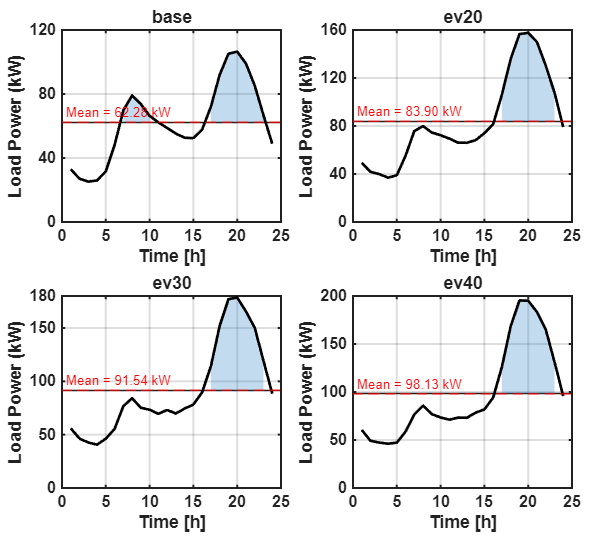

%% ================== FIGURE SETUP (MANDATORY) ==================
close all; clc;

% Physical size for EPS (single-column journal, 2x2 layout)
figW = 18;   % cm
figH = 16;   % cm  <-- σωστό για 2x2 (όχι υπερβολικό ύψος)

figure('Units','centimeters',...
       'Position',[2 2 figW figH],...
       'Color','w',...
       'Renderer','painters');

% Global font control
set(groot,'defaultAxesFontSize',14);
set(groot,'defaultTextFontSize',14);
set(groot,'defaultAxesLineWidth',1.5);
set(groot,'defaultLineLineWidth',2);

%% ================== DATA ==================
scenarios = {'base','ev20','ev30','ev40'};
hours     = 1:24;

peakHours = struct();

%% ================== LAYOUT (2x2) ==================
tiledlayout(2,2,...
    'Padding','compact',...
    'TileSpacing','compact');

%% ================== PLOTTING ==================
for i = 1:numel(scenarios)

    s = scenarios{i};
    y = powerLoadH.(s).p95(:);     % [24x1]
    m = mean(y);

    % Shade only values above daily mean
    yshade = y;
    yshade(y < m) = NaN;

    nexttile; hold on;

    % Shaded peak area
    hA = area(hours, yshade, 'BaseValue', m);
    set(hA,'FaceAlpha',0.25,'EdgeColor','none');

    % Load profile
    plot(hours, y, 'k-');

    % Mean line
    yline(m,'r--',...
        sprintf('Mean = %.2f kW',m),...
        'LineWidth',1.2,...
        'LabelHorizontalAlignment','left');

    % Peak-hour indices
    peakHours.(s) = find(y > m);

    % ---------------- AXES FORMATTING ----------------
    ax = gca;
    ax.FontSize   = 12;
    ax.FontWeight = 'bold';
    ax.LineWidth  = 1.5;
    ax.XLim       = [0 25];
    ax.XTick      = 0:5:25;

    % Scenario-specific Y limits and ticks
    if strcmp(s,'ev20')
        ax.YLim  = [0 160];
        ax.YTick = 0:40:160;
    elseif strcmp(s,'ev30')
        ax.YLim  = [0 180];
        ax.YTick = [0:50:150 180];
    elseif strcmp(s,'ev40')
        ax.YLim  = [0 200];
        ax.YTick = 0:50:200;
    else
        ax.YLim  = [0 120];
        ax.YTick = 0:40:120;
    end

    grid on; box on;

    xlabel('Time [h]','FontWeight','bold');
    ylabel('Load Power (kW)','FontWeight','bold');
    title(sprintf('%s',lower(s)),...
          'FontWeight','bold');

end

%% ================== EXPORT ==================
print(gcf,'unctrl_total_power.eps','-depsc2','-vector');


%% ================== OUTPUT ==================
disp('Peak hours (indices 1–24):');

Peak hours (indices 1–24):


disp(peakHours);

    base: [11×1 double]
    ev20: [7×1 double]
    ev30: [7×1 double]
    ev40: [7×1 double]



## sum of Psecnario - sum of Pbase / sum of Pbase

% Assumptions:
% - variables exist: hours (e.g., 0:23), scenarios (cellstr)
% - powerTotalH.(scenario) fields: .mean, .p95
% - powerLossesH.(scenario) fields: .mean, .p95

figure('Name','Hourly metrics (Load & Losses)','Color','w');
tiledlayout(2,2,'Padding','compact','TileSpacing','compact');

% 1) Hourly mean Pload
nexttile; hold on;
for i = 1:numel(scenarios)
    s = scenarios{i};
    plot(hours, powerLoadH.(s).mean, 'LineWidth', 1.5);
end
grid on; box on;
xlabel('Hour of day'); ylabel('P_{mean} mean (kW)');
title('Hourly Mean P_{load} — all scenarios');
legend(scenarios,'Location','best');

% 2) Hourly P95 P_total
nexttile; hold on;
for i = 1:numel(scenarios)
    s = scenarios{i};
    plot(hours, powerLoadH.(s).p95, 'LineWidth', 1.5);
end
grid on; box on;
xlabel('Hour of day'); ylabel('P_{load} P95 (kW)');
title('Hourly P95 P_{load} — all scenarios');
legend(scenarios,'Location','best');

% 3) Hourly mean P_losses
nexttile; hold on;
for i = 1:numel(scenarios)
    s = scenarios{i};
    plot(hours, powerLossesH.(s).mean, 'LineWidth', 1.5);
end
grid on; box on;
xlabel('Hour of day'); ylabel('P_{losses} mean (kW)');
title('Hourly Mean P_{losses} — all scenarios');
legend(scenarios,'Location','best');

% 4) Hourly P95 P_losses
nexttile; hold on;
for i = 1:numel(scenarios)
    s = scenarios{i};
    plot(hours, powerLossesH.(s).p95, 'LineWidth', 1.5);
end
grid on; box on;
xlabel('Hour of day'); ylabel('P_{losses} P95 (kW)');
title('Hourly P95 P_{losses} — all scenarios');
legend(scenarios,'Location','best');

## Total daily Power Losses

clear
load('statsPower.mat', 'powerLossesH', 'powerLosses_24h');

scenarios = {'base','ev20','ev30','ev40'};
hours = 0:23;                   % x-axis
colors = lines(numel(scenarios));
% Hourly Losses
figure; hold on;
for i = 1:numel(scenarios)
    s = scenarios{i};
    mu  = powerLossesH.(s).mean(:);   % 24×1
    p95 = powerLossesH.(s).p95(:);    % 24×1

    plot(hours, mu,  '-', 'Color', colors(i,:), 'LineWidth', 2,   ...
        'DisplayName', [s ' mean']);
    plot(hours, p95, '--', 'Color', colors(i,:), 'LineWidth', 1.6, ...
        'DisplayName', [s ' P95']);
end
grid on; xlim([0 23]);
xlabel('Hour of day');
ylabel('Losses [kW]');
title('Hourly Losses: Mean and 95th Percentile');
legend('Location','northwest');

%Total Daily Losses
bar_vals = zeros(1,numel(scenarios));
err_std  = zeros(1,numel(scenarios));

for i = 1:numel(scenarios)
    s = scenarios{i};
    bar_vals(i) = powerLosses_24h.(s).mean;   % scalar [kWh or kW⋅h depending on your aggregation]
    err_std(i)  = powerLosses_24h.(s).std;    % same units as mean
end

figure; 
b = bar(1:numel(scenarios), bar_vals, 'FaceColor','flat'); hold on;
b.CData = lines(numel(scenarios));
errorbar(1:numel(scenarios), bar_vals, err_std, 'k.', 'LineWidth', 1.5);

set(gca, 'XTick', 1:numel(scenarios), 'XTickLabel', scenarios);
ylabel('Total daily losses');
title('Total Daily Losses per Scenario (mean \pm std)');
grid on;


clear
load('EV_data.mat');

## Analyzing the EV data generated

% flatten over runs & vehicles
allSoC      = EV_info.ev30( :,3,: );   % [max_EVs×1×N_MC]
allSoC      = allSoC( allSoC>0 );
allCap      = EV_info.ev30( :,4,: );
allCap      = allCap( allCap>0 );
allEneeded  = EV_info.ev30( :,6,: );
allEneeded  = allEneeded( allEneeded>0 );
allDur      = EV_info.ev30( :,5,: );
allDur      = allDur( allDur>0 );
allStart    = EV_info.ev30( :,7,: );
allStart    = allStart( allStart>0 );

% compute basic stats
fprintf('SoC:   mean=%.2f, std=%.2f, [%.2f,%.2f]\n',...
        mean(allSoC), std(allSoC), min(allSoC), max(allSoC));
fprintf('Cap:   mean=%.1f kWh, std=%.1f\n', mean(allCap), std(allCap));
fprintf('Eneed: mean=%.1f kWh, std=%.1f\n', mean(allEneeded), std(allEneeded));
fprintf('Dur:   mean=%.1f intervals, std=%.1f\n', mean(allDur), std(allDur));

% histograms
figure; subplot(2,2,1), histogram(allSoC),   title('Initial SoC');
       subplot(2,2,2), histogram(allCap),   title('Battery Capacity');
       subplot(2,2,3), histogram(allEneeded), title('Energy Needed');
       subplot(2,2,4), histogram(allStart), title('Charge Start Interval');


% EV_profile for "ev10" is [96×N_loads×N_MC]
Pev = EV_load_unctrl.ev30;  % [96×33×100]
% sum across buses → [96×100]
Pev_tot = squeeze(sum(Pev,2));

% mean & p95
m = mean(Pev_tot,2);
p95 = prctile(Pev_tot,95,2);

figure; hold on
plot(1:96, m, 'LineWidth',1.5);
plot(1:96, p95, '--', 'LineWidth',1.5);
legend('Mean EV load','95th %-ile');
xlabel('15 min interval'); ylabel('kW');
title('Aggregate EV Charging Profile'); grid on;

% EV_info.ev10(:,:,mc) col2 is bus indices
N_loads = 37;
allBuses = EV_info.ev30(:,2,:);
allBuses = allBuses(allBuses>0);

counts = histcounts(allBuses, 1:(N_loads+1));
figure; bar(1:N_loads, counts);
xlabel('Bus index'); ylabel('# EVs assigned');
title('EV Assignment Frequency (all runs)'); grid on;

load('MC_KPIS', 'VUF');
N_MC = 100;
% for run mc and EV i, we can pull EV_info.ev10(i,3,mc) and
% the max VD during that run: max( max( VD.ev10(:,:,mc) ) )
%N_EV = max_EVs;
x = []; y = [];
for mc = 1:N_MC
  vd_run = squeeze(VUF.ev50(:,:,mc));   % [96×B]
  peak_vd = max(vd_run(:));
  % average initial SoC across EVs this run
  socs = EV_info.ev50(:,2,mc);
  socs = socs(socs>0);
  x(end+1) = mean(socs);
  y(end+1) = peak_vd;
end
figure; scatter(x,y, 'filled');
xlabel('Mean initial SoC'); ylabel('Peak VD (%)');
title('SoC vs. Network Voltage Deviation'); grid on;

% Quick check: aggregate EV charging power by interval
% (assumes you have EV_load.ev30 as [96×N_loads×N_MC])
Pev_tot = squeeze(sum(EV_load.ev30,2));  % [96×N_MC]

figure; hold on;
m = mean(Pev_tot,2);
p95 = prctile(Pev_tot,95,2);
plot(1:96, m,'LineWidth',1.5);
plot(1:96, p95,'--','LineWidth',1.5);
xlabel('15 min Interval'); ylabel('EV Load (kW)');
title('Aggregate EV Load Profile (ev30)'); grid on;
legend('Mean','95th %ile');

% 1) Compute "incremental EV load" per scenario
scenarios = {'base', 'ev10', 'ev30', 'ev50'}
for s = scenarios
    sc = s{1};
    dP = Praw_load.(sc) - Praw_load.base;   % [96×N_MC]
    EV_only_mean.(sc) = mean(sum(dP,2));    % total EV kW per interval, averaged over runs
end

% 2) Plot EV-only mean vs. time
figure; hold on;
for s = scenarios(2:end)
  plot(1:96, EV_only_mean.(s{1}),'LineWidth',1.5);
end
xlabel('15 min interval'); ylabel('EV kW (mean)');
legend(scenarios(2:end)); title('Mean EV-only Load Profile');
grid on;